clear, clc
close all
datadir = 'G:\A_arousal_analysis\data';
% datadir = '/Volumes/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'FC_Chongqing_s6.mat'))
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'))
load(fullfile(datadir, 'fig_cols.mat'))
cols = cols./255;
cols1 = cols1./255;
FC = atanh(FC);
FC(isnan(FC)) = 0;
FC(~isfinite(FC)) = 0;
label = [zeros(24, 1); ones(30, 1)];
spikes_thresh = 0.25;
outlier = n_spikes > n_timepoints*spikes_thresh;

PE = [ones(numel(label), 1) FC(:, parcel_idx)] * b_pls;
clear FC*

included = ~outlier & patient ~=2;

## classification

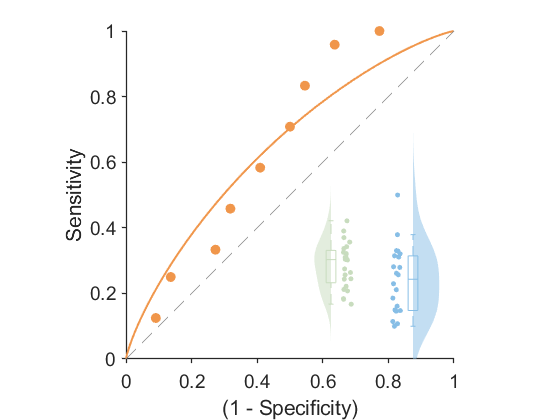

plotRocCurve(PE(included,1), 1-label(included), 'roc_color', cols(1,:), 'g1_color',cols1(8,:), 'g0_color', cols1(4,:))
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)

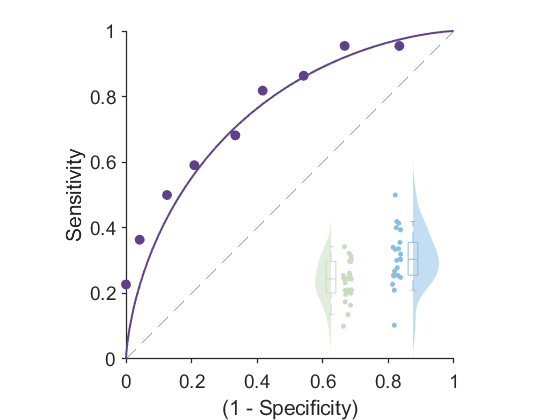

set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_PAES_Chongqing_classification', '-r400')
% close all

plotRocCurve(PE(included,2), label(included), 'roc_color', cols(3,:), 'g1_color',cols1(4,:), 'g0_color', cols1(8,:), 'changeposition', true)
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)

set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_NAES_Chongqing_classification', '-r400')
% close all

## PAES response

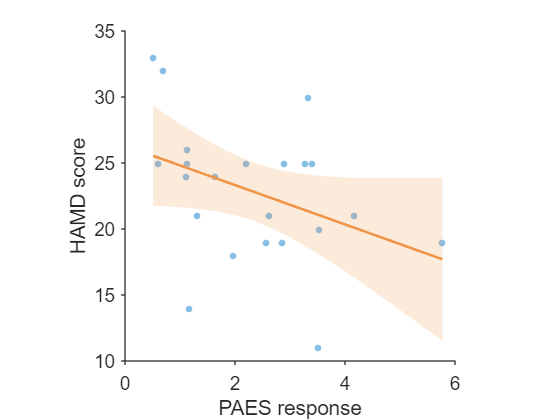

y = HAMD;
x = PE(included&label==1, 1);

tbl = table(x(:), y(:), 'VariableNames', {'x','y'});
mdl = fitlm(tbl, 'y ~ x');

% grid for smooth line + CI
xg = linspace(min(x), max(x), 200)';
[yg, yCI] = predict(mdl, xg, 'Alpha', 0.05);

figure; hold on
scatter(x, y, 25, cols1(4,:), 'filled')

% shaded 95% CI
fill([xg; flipud(xg)], [yCI(:,1); flipud(yCI(:,2))], ...
	cols(1,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% fitted line
plot(xg, yg, 'Color', cols(1,:), 'LineWidth', 2);

xlabel('PAES response');
ylabel('HAMD score'); 
set(gca,'YLim', [10 35], 'ytick',10:5:35, 'XLim', [0 6], 'xtick',0:2:6, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)
axis square

set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_PAES_HAMD_Chongqing', '-r400')
% close all

## NAES response

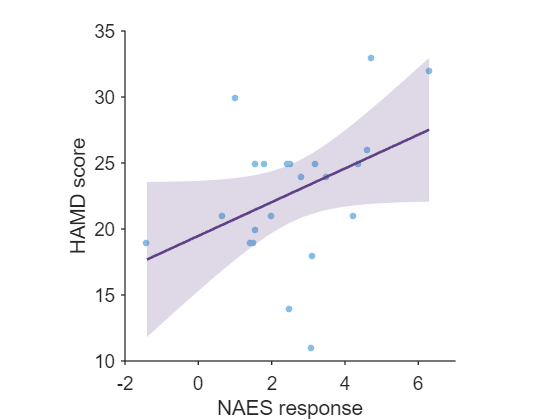

y = HAMD;
x = PE(included&label==1, 2);
tbl = table(x(:), y(:), 'VariableNames', {'x','y'});
mdl = fitlm(tbl, 'y ~ x');

xg = linspace(min(x), max(x), 200)';
[yg, yCI] = predict(mdl, xg, 'Alpha', 0.05);

figure; hold on 
scatter(x, y, 25, cols1(4,:), 'filled')

% shaded 95% CI
fill([xg; flipud(xg)], [yCI(:,1); flipud(yCI(:,2))], ...
	cols(3,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none');

% fitted line
plot(xg, yg, 'Color', cols(3,:), 'LineWidth', 2);

xlabel('NAES response');
ylabel('HAMD score'); 
set(gca,'YLim', [10 35], 'ytick',10:5:35, 'XLim', [-2 7], 'xtick',-2:2:6, 'tickdir', 'out');
set(gca,'FontName','Helvetica','FontSize',14, 'LineWidth', 1)
axis square

set(gcf, 'Color', 'w');
% set(gcf, 'PaperUnits', 'inches');
% set(gcf, 'PaperPosition', [0 0 3.5 3.5]);
% print('-dtiff', 'A_NAES_HAMD_Chongqing', '-r400')
% close all